## Sketch

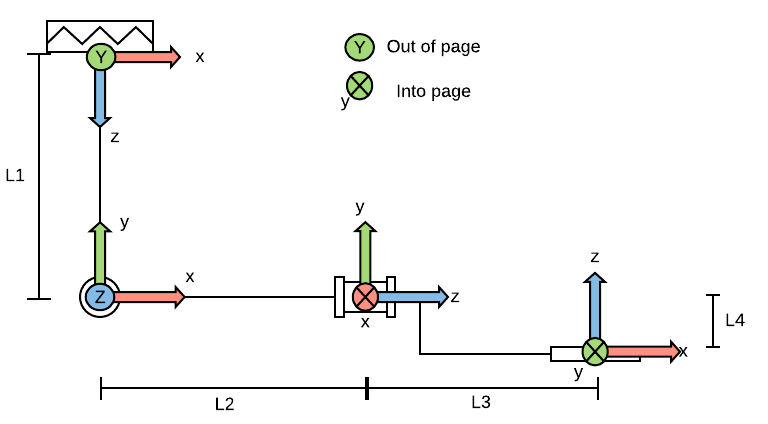

## Lengths/Dimensions

%clear all;
L1 = 0.0;
L2 = 0.2;
L3 = 0.2;
L4 = 0.0;

## Link Definitions

% L = Link ([Th d a alpha])
L(1)= Link([0 0 0 -pi/2],'modified');
L(1).qlim = ([0, pi/2]);
L(2)= Link([0 L2 0 pi/2],'modified');
L(2).qlim = ([-pi/2, pi/2]);

## Serial Kinematic Link

% plotOpt = ['name','pmj','workspace', [-1 1 -1 1 -1 1]]
pmj=SerialLink(L,'name','pmj');

% pmj = SerialLink(L,'plotopt',plotOpt);

## Tool Frame

toolHT=transl(0,-L4,L3)*troty(-pi/2);
pmj.tool=toolHT;

## Base Frame

baseHT = transl(0,0,-L1);
pmj.base = baseHT

 
pmj = 
 
pmj:: 2 axis, RR, modDH, slowRNE                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|    -1.5708|          0|
|  2|         q2|        0.2|          0|     1.5708|          0|
+---+-----------+-----------+-----------+-----------+-----------+
tool:    t = (0, 0, 0.2), RPY/xyz = (0, -90, 0) deg              
 


## Kinematic Chain

s = pmj.trchain('sym')

s = 'Rz(q1)Rx(-90)Rz(q2)Tz(L1)Rx(90)'

## Plot Manipulator

q1 = pi/2; q2 = 1;
%pmj.teach([q1, q2],'approach')

## Forward Kinematics

toolPos = pmj.fkine([q1, q2]);
disp(toolPos)

            1-8.461e-17 1.844e-17       0.4
    6.123e-17    0.5403   -0.8415 2.449e-17
    6.123e-17    0.8415    0.5403 2.449e-17
            0         0         0         1


## Inverse Kinematics

Target Pose

poseHT = transl(0.4,0,0)*trotx(pi/2);
trplot(poseHT, 'frame', 'Trgt', 'color', 'm','length', 0.3)

Inverse kinematics with ikcon (with joint limits)

%initial guess
q0=[0, 0];
% q2 = pmj.ikinem(poseHT)
% q1= pmj.ikine(poseHT,q0,'qlimits','mask',[1,0,1,1,0,0])
[q,err] = pmj.ikcon(poseHT,q0);
q_deg = q * 180/pi;

Calculated Joint angles

display(q_deg)

q_deg =     90    90


display(err)

err = 2.8495e-31

Plotting Result

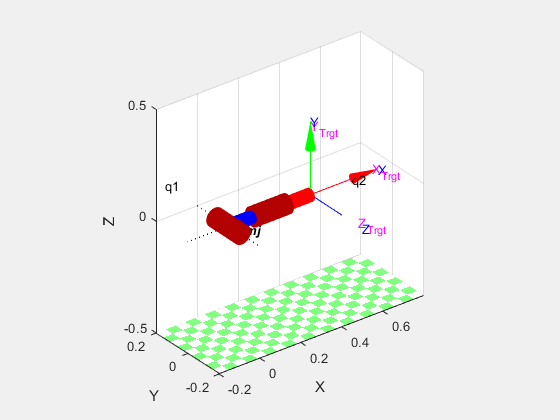

pmj.plot(q,'wrist','jaxes','nobase', 'noshadow', 'noshading',...
        'floorlevel',0.4,'raise','zoom',0.5,... 
        'workspace', [-0.2 0.8 -0.2 0.2 -0.5 0.5])